% Parameterize the arm
rho = 0.0254; % M, Radius

% Orientation of muscles in world frame:
tilt_angle = pi/4;

% Orientation of base curve (x = up):
R_g_o = eul2rotm([0, -pi/2, 0], 'xyz');

% Posese of muscle in world frame
% Muscles are arranged in equilateral triangle with radius rho
g_o = SE3(R_g_o, [0 0 0]); % Base-curve frame
g_muscles = Arm3D.generate_g_muscles(rho, g_o, 3, tilt_angle);

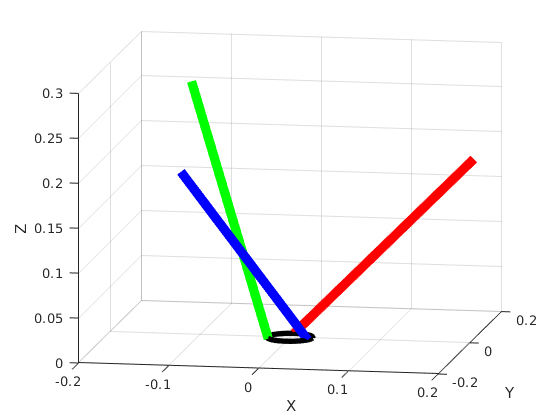

l_0 = 0.4; % Default length

helical_arm_obj = HelicalArm(g_o, g_muscles, l_0);
helical_arm_obj.rho = rho;

fig = figure();
ax = axes(fig);
line_options_muscles = struct("LineWidth", 7);
line_options_circles = struct("LineWidth", 4);
helical_arm_obj.initialize_plotting(ax, ...
    "line_options_circles", line_options_circles, ...
    "line_options_muscles", line_options_muscles, ...
    "resolution", 40);

border_length_cm = 20;
xlim(ax, [-1, 1] * border_length_cm/100);
ylim(ax, [-1, 1] * border_length_cm/100);

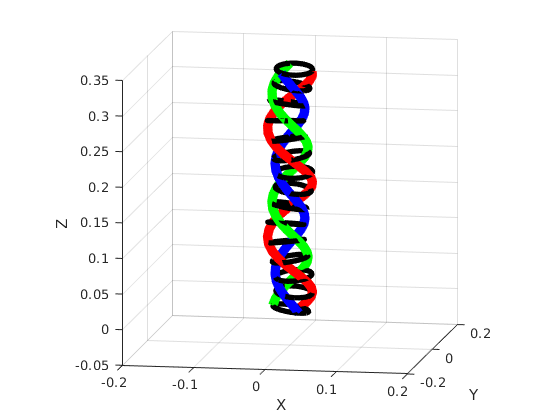

l_A = 0.565; % Red
l_B = 0.48; % Green
l_C = 0.425;  % Blue

v_l = [l_A; l_B; l_C];
helical_arm_obj.update_arm(v_l);